# Defining Requirements 

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

When you think of problem-solving, do textbook word problems come to mind? These problems often include statements like "Solve for $Z$ as a function of $X$ and $Y$, when $X=2$ and $Y=4$." Parts of this statement serve as requirements by constraining the solution for $Z$. Requirements simplify problem-solving by setting boundaries around problems with many variables. Without such constraints, a task such as "Solve for $Z$" would lack the necessary context. In this script, we'll explore how to formulate and test requirements for systems we aim to solve. 

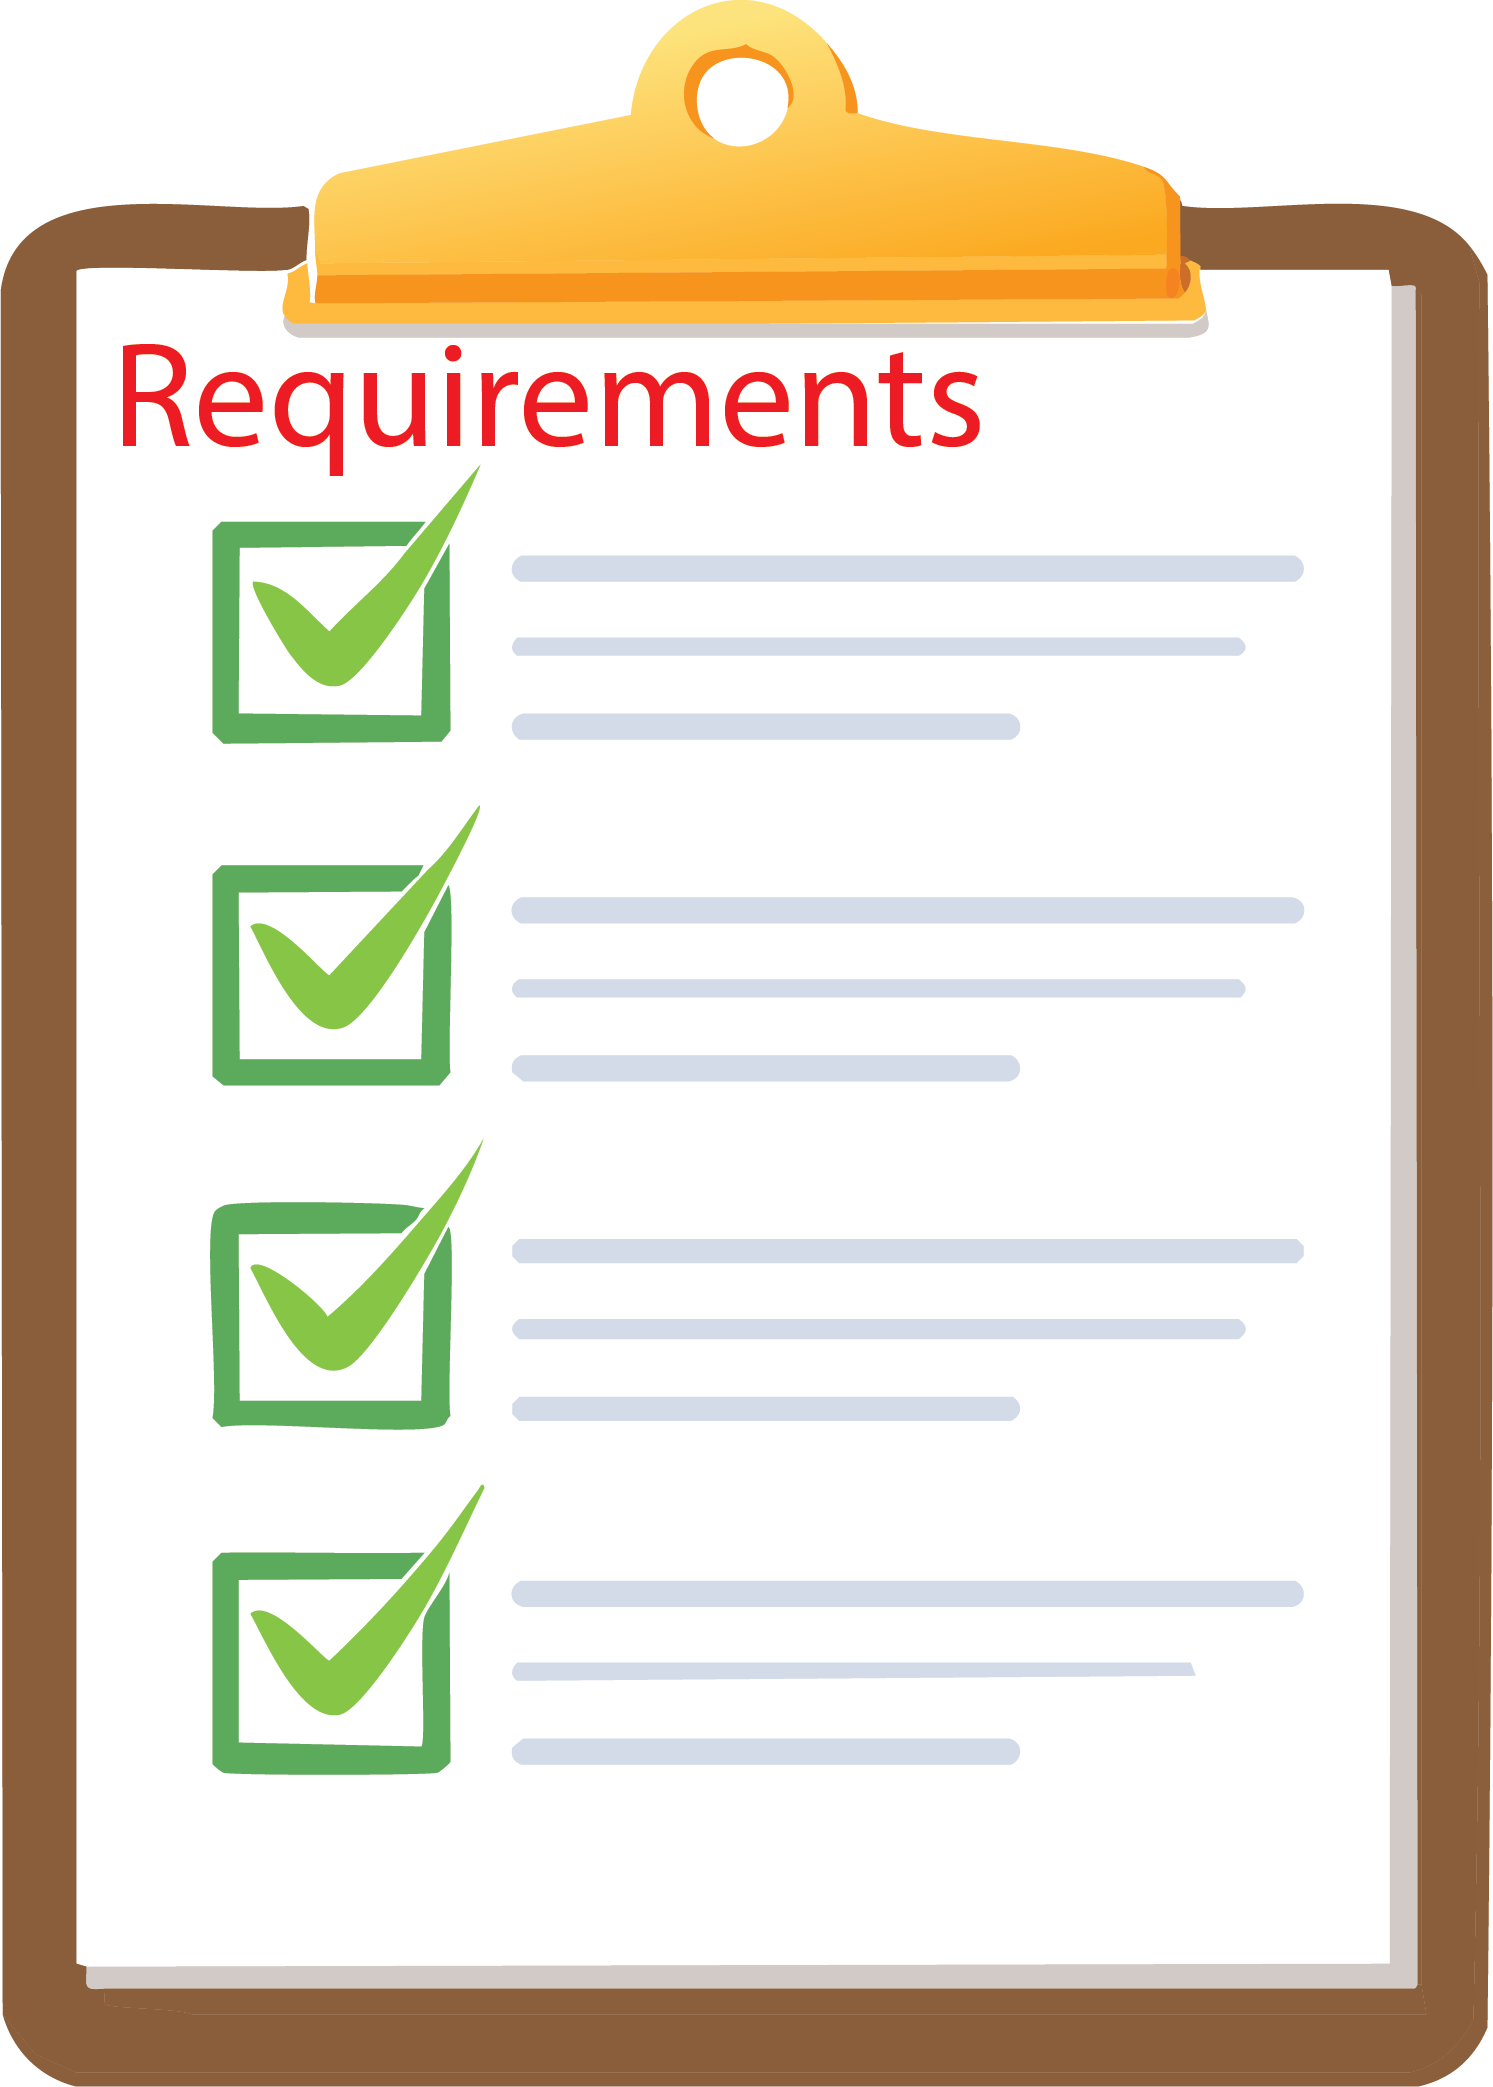

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted) and [Simulink Onramp](https://matlabacademy.mathworks.com/details/simulink-onramp/simulink), both are free 2 hour online tutorial that teaches the essentials of MATLAB and Simulink, respectively.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Introduction to requirements

Requirements are constraints or bounds that provide more focus to a problem and makes the solution verifiable. Engineering teams use these constraints to build a safe and reliable product. Requirements may also be subjective depending on the audience it is intended for. That is, a requirement may look different from a manufacturer's point of view compared to a consumer's point of view. Requirements can be related to specific components or even entire systems. During testing of these components or systems, problems can occur that can cause a test to fail. Having a set of requirements to refer to helps in knowing where to look when issues arise.

### Problem statements

Problem statements concisely describe a problem and the needs that must be addressed, showing the gap between current and desired state. Problem statements pave the way for formulating clear and precise requirements. Before requirements can be written, the first step is to ensure a proper understanding of the problem statement. *At the beginning of the problem-solving process, there are two questions that need to be addressed:*

interaction1("What is the problem we are solving? Why is it a problem to be solved?");

Correct! What and why are the primary concerns at the beginning stage of problem solving. What problem are we trying to solve, and why are we trying to solve it?


*A well-defined problem statement is usually motivated by a purpose or need and is composed of the essential questions that need to be addressed.* The term "problem" can occasionally evoke a negative connotation. Instead, consider it as an opportunity or a challenge to overcome, offering a chance to solve an issue or provide assistance to someone.

 **Exercise 1. **Imagine you are an HVAC manufacturer being contracted by customer. Examine a sample HVAC problem statement and break it down into its key components:

 
disp("As part of Heat&Cold Corp., a leading HVAC design and manufacturing company, we are tasked" + newline + "with developing an innovative and cost-effective HVAC system that significantly reduces energy" + newline + "consumption in households. Our goal is to achieve a 20% reduction in energy usage to minimize" + newline + "the carbon footprint of our latest unit while maintaining or enhancing indoor air quality and" + newline + "comfort levels. To ensure affordability, the price of the new unit should not exceed a 5%" + newline + "increase over the previous generation.")

As part of Heat&Cold Corp., a leading HVAC design and manufacturing company, we are tasked
with developing an innovative and cost-effective HVAC system that significantly reduces energy
consumption in households. Our goal is to achieve a 20% reduction in energy usage to minimize
the carbon footprint of our latest unit while maintaining or enhancing indoor air quality and
comfort levels. To ensure affordability, the price of the new unit should not exceed a 5%
increase over the previous generation.


interaction2("Develop a Cost-Effective HVAC");

Correct! The problem to be solved is developing a cost-effective HVAC system.


interaction3("To Reduce Energy Consumption");

Correct! The reason behind solving the problem is in support of reducing energy consumption.


 **Reflect**. Revisit the problem statement above and note the potential competing priorities involved: developing an energy-efficient and cost-effective HVAC system while preserving the existing air quality standards of traditional, less efficient systems. While the primary focus is on enhancing energy efficiency and reducing costs, it is crucial to also consider additional factors, such as air quality, as you develop your solution. These considerations will be explored in later sections.

### Writing requirements

A well-defined problem statement simplifies creating essential requirements, using the term ***shall*** to emphasize necessity for functionality and safety. Including measurable quantities in requirements ensures verifiability. The requirements definition phase, often the longest in the design lifecycle and termed the "churn," involves extensive effort to understand customer needs and the problem at hand. Let's examine a potential requirement from the previous HVAC problem statement:

 
disp("The HVAC system shall be cost-effective and energy efficient" + newline + "while providing the same/better air quality and comfort.")

The HVAC system shall be cost-effective and energy efficient
while providing the same/better air quality and comfort.


 **Note**. It is discouraged to use statements such as ***shall not*** when writing requirements, as it may create confusion. Focus on what a system should do instead of what it shouldn't.

### Types of requirements 

The sample requirement above is what would be considered a high-level requirement. It paints a broad picture for the goal of this problem and provides bounds in which we will work within. However, at this level, there is only so much that can be done with this information. As we get into lower level requirements, the solution begins to take shape. The table below provides examples of typical requirements encountered during a project:

 **Note**. Observe that the desired requirement example has a *should* statement instead of a *shall* statement. Desired requirements are not rigid, they are a goal to try and achieve, if possible, while meeting the other mandatory constraints.

 **Exercise 2. **From an HVAC manufacturer perspective, which hierarchy do you think the following sample requirement belongs to: *The HVAC system should cost $6,000 or less*. Please select one answer and click the **Submit Answer** button below. 

exerciseSol2(...
    A = false, ...
    B = false, ...
    C = false, ...
    D = true);

Correct! This requirement is desired because it can add value if the cost is lower than what the market is currently offering for comparable HVAC systems.


## Creating requirements

** Demonstration**. As you may have already guessed, the more complex a system is, the more requirements it may have. Let's revisit the bungee jumping example modeled as a mass-spring-damper in [Introduction to Problem Solving](matlab:open('.\IntroToProblemSolving.mlx')). We will begin by defining a problem statement and associated requirements for a *worst case scenario*, a very hot day with a larger-sized adult. ***Then, we will link the requirements to the model and test them to ensure all requirements are covered.***

  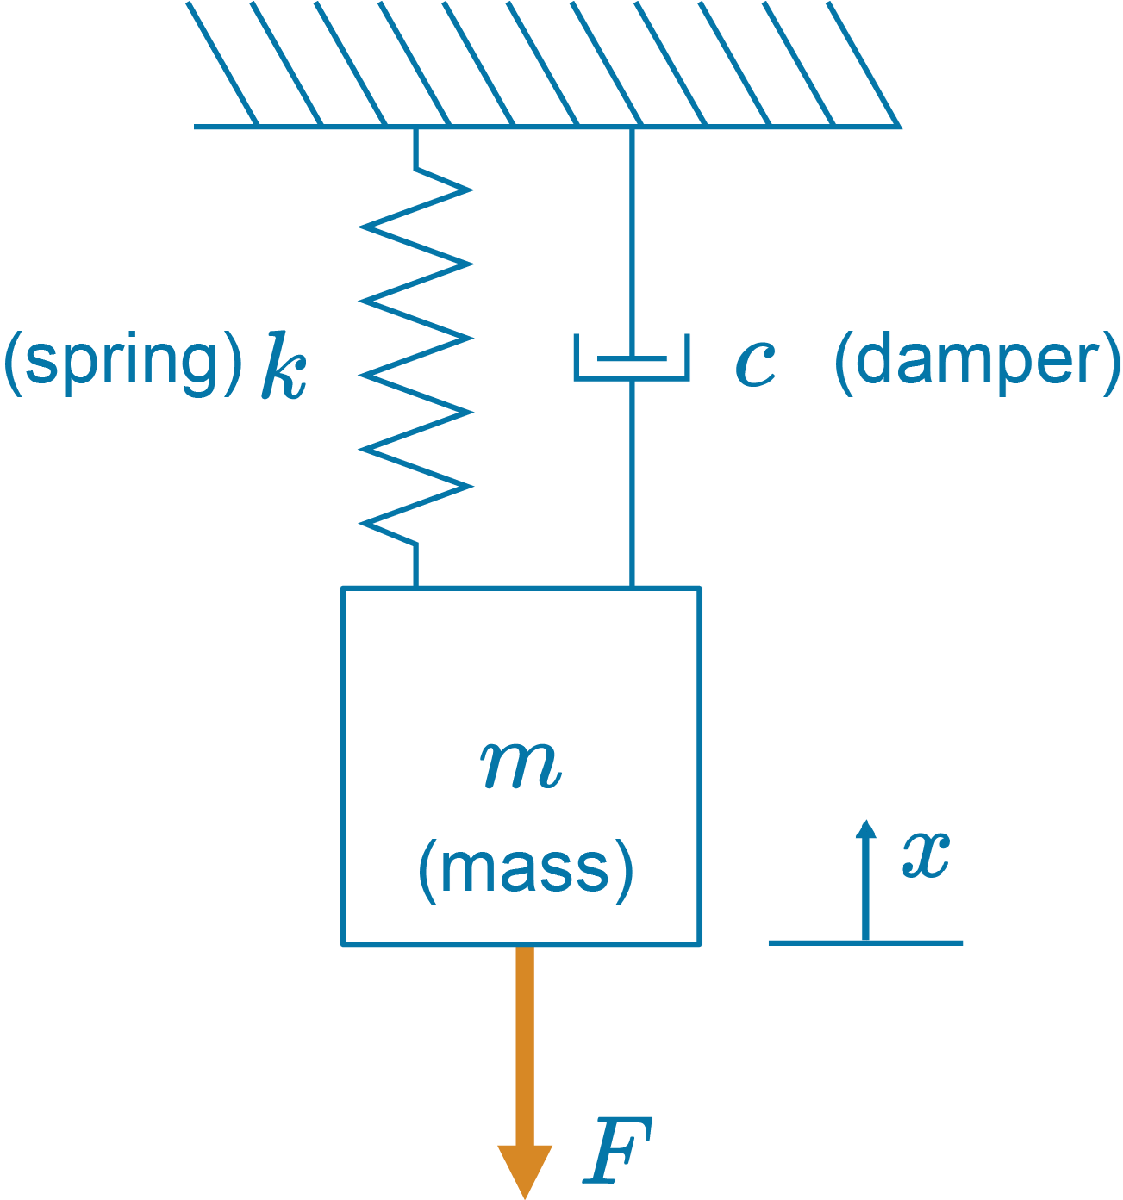 

 **Note**. A few assumptions have been made for simplicity in limiting the number of requirements for this example. With hotter, less dense air, the drag force acting on the bungee system is smaller, reducing the resistance on the bungee jumper falling. Because the statement mentions "usage year round" and "high temperature" operation, it is implied that the minimum (cold) temperature will be accounted for ($\uparrow \textrm{Air}\;\textrm{Density}=\;\uparrow \textrm{Drag}\;\textrm{Force}$). Also, the usage of "adult" implies an average minimum size (mass and area) will be accounted for if the maximum is the baseline. In a normal scenario, factors such as minimum mass, adult surface area, and temperature would be considered derived requirements if not explicitly called out in the problem statement.

  **Try**. Currently, we have a mathematical model that represents the bungee jumping system. Now, we want to apply some constraints to this model so that we can verify it meets the customer's needs. To do this, we will use the [Requirements Editor](https://www.mathworks.com/help/slrequirements/ref/requirementseditor-app.html) to add the requirements from the table above into the mathematical model. 

 

% Clear previous sample requirements and update links
slreq.clear();
slreq.app.CallbackHandler.onRefreshAllHyperlink('standalone');

% Open Requirements Editor
slreq.editor;

% Check if project is open and add path
if isempty(matlab.project.rootProject)
    addpath(genpath(pwd));
end

Begin by using the   button to add a new requirement set. Name the set **SampleRequirements**. From the table above, all high-level requirements will be considered parent requirements, while all low-level requirements will be considered child requirements. When you are done adding requirements, the editor shall have *one parent* requirement with *five children*. Use the following steps to update the **Overall & Temperature Requirements**: 

- Select the "SampleRequirements" index in the editor window and add a requirement using the dropdown menu on the   button. This new requirement will be considered the parent. 

- To add a child requirement to the parent, select the "1" index in the editor to access the "Add Child Requirement" option in the same dropdown menu as step 1. You should now have the parent (1 - Overall) attached to one child (1.1 - Temperature). 

- Copy/paste the requirements from the table above into the "Summary" section for index "1" and "1.1" in the editor (window pane to the right). 

Once the requirement has been added, save this new requirement set in your current directory by using the   button. **We will keep the editor open for future steps.** The remaining requirements will follow the same steps above. ***OPTIONAL:**** You don't have to create all 5 requirements. A future section will have all the requirements, links, and tests already created for you*.

setFlag = true;
% Display image of expected requirement set result
if setFlag
    I = imread("Images/SampleReqSet.png"); %#ok<UNRCH>
    J = imresize(I,0.75);
    imshow(J);
end

 **Pro-tip. **Use the dropdown menu on the   button to change the view of the requirements set. The default view is tabular. Using this button, you can also change it to a document-style view. If you are unable to see this button, expand your Requirements Editor window.

## Linking requirements to a model

We've now created a set of requirements for the bungee jumping problem. Linking requirements to a model establishes a traceability link, ensuring the coverage of requirements during systems testing. This process helps to confirm a complete design, allowing development to proceed with confidence in the design's accuracy. 

  **Try**. Now, we will link the requirements to specific blocks in the model. Let's open our bungee jumping model with drag:

 

% Open simulink model for bungee jumping with drag for requirements 
open_system("Models/BungeeJumpingDragSample.slx");

 **Pro-tip. **Requirements can also be linked to lines of code if your model uses [MATLAB function](https://www.mathworks.com/help/simulink/slref/matlabfunction.html) blocks. 

The following table describes the link from our requirements to the model:

 Select the **"Drag Force"** block in the model and then select the **Temperature Requirement** in the Requirements Editor. Continuing in the Requirements Editor, use the dropdown menu on the   button to add a link from the block to the requirement by **selecting the first option, "****Link from 'Block name' (Block type)**."

 **Pro-tip. **Use the drop down menu for the   button and select **Verification Status. **This will add a "Verified" column to the Requirements Editor window, which provides a pass/fail view for linked requirements. If you cannot see it, readjust the size of the "Summary" column width.

To preserve the newly linked requirements between the Requirements Editor and the model, you must save your Simulink model by using the   button. This will create a `BungeeJumpingDragSample~mdl.slmx` file. **Close the Simulink model window when you are finished. **The remaining links will follow the same steps above. In the Requirements Editor, after a requirement is selected, check the "Links" section in the window to the right. It will display how the requirement is implemented, which will be from a block in the model. In the Requirements Editor window, the Verified column shows whether or not the requirement has been met.** If the bar is clear, you have implemented the requirement correctly. The clear bar tells you the requirement has not been verified yet. **

% Display image of expected link set result
linkFlag = true;
if linkFlag
    I = imread("Images/SampleLinkSet.png"); %#ok<UNRCH>
    J = imresize(I,0.75);
    imshow(J);
end

Here is a list of the remaining requirements to link to associated blocks:

 **Pro-tip. **In the Requirements Editor, once the requirements have been linked to a model, you can use the   button to create a traceability matrix for your model. This view creates a matrix to easily characterize where requirements are linked in the model and vice-versa, to ensure requirements coverage of your system. First, select the   button. Next, select the `SampleRequirements.slreqx` requirement set and the `BungeeJumpingDragSample.slx` model for the artifacts. Last, select "Generate Matrix". **Close this window when you are finished.**

 **Exercise 3. **True or False. When linking requirements, the parent requirement shall also be linked to a block. Please select one answer and click the **Submit Answer** button below. 

exerciseSol3(...
T = false, ...
F = true);

Correct! The keyword used is shall. Linking parent (high-level) requirements is not firm.
If all of the child (low-level) requirements are met under a parent requirement,
that parent requirement is satisfied and does not need to be linked directly.


## Linking tests to requirements

Now that we have created and linked requirements to a model, we have to create tests to verify that the requirements have been satisfied in the model. *A requirement is only as useful as the test written to verify it*. In a model, there may be tests on inputs to the system, outputs, or variables used during the simulation. The next step is to create tests and link them to the associated requirements to ensure our model is meeting the requirements outlined from the earlier problem statement. Since we are focused on five requirements, we will have five tests to write. 

  **Try**. We will create and link tests to requirements by opening the [Simulink Test Manager](https://www.mathworks.com/help/sltest/ref/simulinktestmanager.html):

 

% Close current session of requirements and test files
sltest.testmanager.clear;
sltest.testmanager.clearResults;

% Open Simulink Test Manager
sltest.testmanager.view;

Begin by using the dropdown menu on the   button to add a new test file. Name the file **SampleTests**. *New Test Suite 1* and *New Test Case 1* will be created in the Test Browser window to the left after saving the test file. A tab for New Test Case 1 will open in the test manager as well. When you are done adding tests, the manager shall have *one test suite* with *five test cases*. In the Test Browser, rename New Test Case 1 to *Temperature Test* by right-clicking on it or using F2. Rename *New Test Suite 1* right above the test case to *Sample Test Suite* following the same procedure. Use the following steps to update the **Temperature Test**:

- In the Requirements Editor, select the temperature requirement. Then, in the Test Manager >> Temperature Test Tab >> **Requirements** >> "Add" drop down menu, select the last option: *Link To Selected Requirement*. The temperature requirement should now be linked to its corresponding test. This will create a SampleTests`~mldatx.slmx` file to preserve the new linkages.

- Under **System Under Test **>> Model, select the   icon to add the current `BungeeJumpingDragSample` model. 

- In the same section, under **Simulation Settings And Release Overrides**, check the "Stop Time" check box and change the value to 50. 

- Finally, under **Callbacks **>> Cleanup, copy/paste the following code in the window:

This completes the test setup for the temperature requirement. Once the test information has been added, save this new test set in your current directory by using the   button. The remaining tests will follow the same steps above. In the Requirements Editor, after a test is added, check the "Links" section in the window to the right. It will display how the test is verified, which will be from a test in the Test Manager. In the Requirements Editor window, the "Verified" column shows whether or not the requirement has been met. **If the bar is yellow, you have created a verification step for the requirement correctly. The yellow bar tells you the requirement has a test but has not been implemented yet.**

% Display image of expected test set result
testFlag = true;
if testFlag
    I = imread("Images/SampleTestSet.png"); %#ok<UNRCH>
    J = imresize(I,0.75);
    imshow(J);
end

Here is a table that shows the remaining requirements attached to its relevant test criteria:

 **Pro-tip. **To create a new test case for the other requirements, right click on Sample Test Suite, select New, and add a "Baseline Test". For the remaining test cases, update the variable name/value in step 4 based on the test criterion in the table.

 **Note**. It is okay if your Requirement Index/Requirement in the Requirements Editor does not match the table above. Be sure to match the correct test to its corresponding requirement. 

### Verifying requirements

Let's take a step back and look at what we have done up to this point and why. We took requirements and attached them to variables in the bungee mathematical model, which are measurable components. Next, we attached the requirements to tests to ensure they are satisfied. Let's say you encountered a failed requirement during testing. That failed test has some criterion that is linked back to a variable in the mathematical model. In problem solving, these connections provide artifacts to follow when you encounter problems in your design that must be addressed. The intent of verification is to ensure we are solving the problem as designed.

** Demonstration**. Now that you have learned to create and link requirements and tests to models, let's open up a ***previously saved bungee jumping example ***and begin verifying the requirements. Use the button below to open the example model and associated requirements and test sets. 

 **Warning**. *Using this button will also close the previous model, requirements, and tests that were open*. *You will be prompted about choosing to save those previous files. *

 

% Close previous model and current session of requirements and test files
close_system("Models/BungeeJumpingDragSample.slx",0);
clear;
slreq.clear();
sltest.testmanager.clear;
sltest.testmanager.clearResults;

% Open bungee jumping example
open_system("Models/BungeeJumpingDragReqx.slx");
slreq.open("Data/BungeeRequirementsBase.slreqx");
slreq.app.CallbackHandler.onRefreshAllHyperlink('standalone');
sltest.testmanager.view;
sltest.testmanager.load("Data/BungeeTestsBase.mldatx");

Once open, in the Test Manager, select the **Bungee Test Suite **in the Test Browser. Then select the   button. Now that we have linked tests, we can observe whether each test passed or failed and why. You can view details about the tests in the **Results and Artifacts** tab. In the Requirements Editor, you can also observe if the test passed (green) or failed (red) for the given requirement. From the test run, it seems that some tests passed while others failed. We can attribute this to the values for density, mass, and area not being updated in the MATLAB Workspace to meet our test criterion. Let's update them to the values from the table above:

 

% Update Density, Mass, and Area parameters to coincide with tests
rho = 1.093; 
m = 120; 
A = 2;

% Feedback
warning("Parameters updated! Please return to the Test Browser and run the Bungee Test Suite again. Then check the results!")

  **Try**. Run the **Bungee Test Suite **in the Test Browser with the new values. After running the tests a second time, we can see that all of our tests passed! That means our model should meet the standards for a good design, right? Now let's see what the result of our bungee jumper position is under these constraints.

reqFlag = true;

if  reqFlag 
    % Run bungee cord model with drag
    outReq = sim("Models/BungeeJumpingDragReqx.slx","StopTime","50"); %#ok<UNRCH>

    % Plot the bungee cord position
    simData = outReq.logsout{1}.Values;
    t1 = simData.Time;
    p1 = simData.Data;
    t2 = t1;
    p2 = zeros(size(t1,1),1);
    plot(t1,p1,'-',t2,p2,'--','LineWidth',2);
    grid;
    yticks(-60:10:80);
    xlabel('Time (sec)'); ylabel('Position (m)');
    title('Bungee Jumper Position');
    legend("Bungee Position with Drag","Ground")

    % Feedback
    pause(1)
    warning("Oh no! We have a problem in our bungee jumping system design!" + newline + "Under these constraints, the bungee jumper will make contact with the" + newline +  "ground after the initial jump!")
end

It appears that we may have missed some requirements in our initial interpretation of the problem statement. *We certainly don't want our designed system to create a safety hazard*. Fortunately, this scenario is unfolding in a virtual model rather than real-life testing. At times, seemingly obvious requirements, such as preventing a bungee jumper from coming in contact with the ground, aren't initially considered. Such requirements are known as derived requirements:

 **Reflect**. The last requirement is listed as desired, which provides some margin for options. A cord with a lower spring constant may also be more reasonable to purchase or develop. Additionally, how much leeway is there on this requirement? Can it be 6 m? What about 10 m? This answer will depend on other competing requirements that must also be met. 

 **Note**. Realistically, a spring constant for a cord would not be something that is modified. However, a measured spring constant from a model can be taken and utilized to purchase or develop a cord that meets the needs of a system.

By adding these requirements, we'll see if each condition was met after simulation, and hopefully satisfy the overall system requirements. The derived requirement must pass its test while the desired requirement does not have to pass its test. Load and view the updated requirements and tests with the following button:

 

% Close previous model and current session of requirements and test files
close_system("Models/BungeeJumpingDragReqx.slx",0);
slreq.clear();
sltest.testmanager.clear;
sltest.testmanager.clearResults;

% Open bungee jumping example with derived requirements
open_system("Models/BungeeJumpingDragReqxDerived.slx");
slreq.open("Data/BungeeRequirementsNew.slreqx");
slreq.app.CallbackHandler.onRefreshAllHyperlink('standalone');
sltest.testmanager.view;
sltest.testmanager.load("Data/BungeeTestsNew.mldatx");

  **Try**. Typically, the larger the spring constant, the higher the cost to develop the spring. Conduct a trade study by adjusting the spring constant (k) slider below to balance meeting the safety requirement for this system and the affordability of the cord. Remember, we also want the bungee jumper to experience maximum thrill! View the updated results in the Test Manager window and the updated bungee position plot here:

k =50;

% Run Model
outReq = sim("Models/BungeeJumpingDragReqxDerived.slx","StopTime","50");

% Run Tests
sltest.testmanager.run;

% Plot Results
simDataNew = outReq.logsout{1}.Values;
t3 = simDataNew.Time;
p3 = simDataNew.Data;
t4 = t3;
p4 = zeros(size(t3,1),1);
plot(t3,p3,'-',t4,p4,'--','LineWidth',2);
grid;
if k < 50
    yl = ylim;
    yticks(yl(1):10:80)
else
    ylim([-10 80]);
    yticks(-10:10:80);
end
xlabel('Time (sec)'); ylabel('Position (m)');
title('Bungee Jumper Position');
legend("Bungee Position with Drag","Ground")

% Feedback
pause(1)
if min(p3) < 5 && k < 50 
    error("The designed system has a spring constant of k = " + num2str(k) + " N/m" + newline + "and a minimum height above the ground of x = " + num2str(min(p3)) + " m." + newline + "This violates the safety requirement for the bungee jumper!")
elseif min(p3) >= 5 &&  k == 50 
    disp("Correct! The designed system has a spring constant of k = " + num2str(k) + " N/m" + newline + "and a minimum height above the ground of x = " + num2str(min(p3)) + " m." + newline + "This configuration satisfies both additional requirements!")
elseif min(p3) >= 5 && k > 50
    warning("The designed system has a spring constant of k = " + num2str(k) + " N/m" + newline + "and a minimum height above the ground of x = " + num2str(min(p3)) + " m. While" + newline + "this satisfies the safety (derived) requirement, it does not" + newline + "satisfy the desired result of having an affordable spring constant" + newline + "and attaining maximum thrill.")
end

Correct! The designed system has a spring constant of k = 50 N/m
and a minimum height above the ground of x = 5.2948 m.
This configuration satisfies both additional requirements!


  **Pro-tip**. Both the Requirements Editor and the Test Manager can both be opened programmatically or through apps via the MATLAB Toolstrip under the **APPS** tab.

Let's clean up our working environment using the button below:

 

% Close all bungee example windows and clear workspace
close_system("Models/BungeeJumpingDragReqxDerived.slx",0);
clear;
slreq.clear();
sltest.testmanager.clear;
sltest.testmanager.clearResults;
sltest.testmanager.close;

% Check if project is open and remove path
if isempty(matlab.project.rootProject)
    warning('off','MATLAB:rmpath:DirNotFound');
    rmpath(genpath(pwd));
end

## Regulatory requirements

When handling customer requirements, it's crucial to consider the regulatory environment, which consists of government entities ensuring public safety in industries like aviation, automotive, and medical devices. These government bodies mandate requirements that must be met before market release. Over time, regulations will evolve, introducing new requirements for product or service development.

### Systems project: Delivery drone

** Application. **In the United States, delivery drones must show completion (certification) of requirements **mandated** by the Federal Aviation Administration (FAA) to legally fly and deliver packages. The specific section for delivery drone certification is 14 CFR 135 [3] of the Code of Federal Regulations (CFR). [In the last script](matlab:open('./IntroToProblemSolving.mlx')), we discussed the main project for this module being a delivery drone. We will define a requirement and test for this problem based on regulatory considerations.

***14 CFR 135.203(a)(1) - Except for takeoff or landing, no person may operate an aircraft under visual flight rules (VFR) at an altitude of less than 500 feet above the surface and less than 500 feet horizontally from any person, structure, or vehicle. ***

 **Exercise 4. **What would be a reasonable requirement in support of 14 CFR 135.203(a)(1) if the delivery drone is **NOT** taking off or landing? Please select one answer and click the **Submit Answer** button below. 

exerciseSol4(...
    A = true, ...
    B = false, ...
    C = false, ...
    D = false);

Correct! This requirement best encompasses the request of the regulatory standard.


 **Exercise 5. **What would be a valid test criterion for the previous requirement? Please select one answer and click the **Submit Answer** button below.

exerciseSol5(...
    A = false, ...
    B = false, ...
    C = true, ...
    D = false);

Correct! This test criterion satisfies the previous requirement.


## Managing requirements

***"If the only tool you have is a hammer, you tend to see every problem as a nail." - Abraham Maslow (Psychologist)***

In industry, requirement sets are managed using a range of tools, each providing specific benefits like traceability, import/export capabilities, and intuitive interfaces with improved visualization. Just as with problem modeling, choosing the right combination of tools is essential, as no single tool typically meets all the needs for a given problem. While MATLAB/Simulink has been our primary choice for requirement management in this script, alternatives such as Excel and DOORS are also available. Regardless of the initial tool you choose, MATLAB supports easy integration with these platforms, simplifying the process of importing and managing requirements, and thus conserving time and effort. For more options that integrate with MATLAB, please refer to the Further Exploration section.

## Next Steps

This script covered understanding problem statements and how to write and test requirements. In the next section, we will start the process of problem solving of a delivery drone by decomposing requirements into tangible actions. 

## Glossary

**Requirement** - A documented need or condition that a particular product, service, or system must satisfy. (↑ Return to Text)

**Verification **- The process of establishing truth, accuracy, or validity that the problem being solved is the correct one. (↑ Return to Text)

**HVAC** - Heating, Ventilation, and Air Conditioning. (↑ Return to Text)

**AQI **- Air Quality Index. A tool for communicating about outdoor air quality and health. (↑ Return to Text)

**Traceability** - The ability to track and document relationships between different elements of a system throughout its development lifecycle. (↑ Return to Text)

**Trade Study **-  A process where different options or solutions to a problem are compared against a set of criteria to identify the most balanced and optimal choice. (↑ Return to Text)

**Certification** - In the context of aviation, this means the FAA has confirmed that a product or operation meets FAA safety requirements and standards, ensuring safe operation for the public. (↑ Return to Text)

## Further Exploration

- [Requirements Toolbox](https://www.mathworks.com/products/requirements-toolbox.html)

- [Getting Started with Requirements Toolbox](https://www.mathworks.com/help/slrequirements/getting-started-with-requirements-toolbox.html)

- [Import and Integrate Requirements into MATLAB](https://www.mathworks.com/help/slrequirements/import-and-integrate-requirements.html?s_tid=CRUX_lftnav)

- [Simulink Test](https://www.mathworks.com/products/simulink-test.html)

- [Specify Test Properties in the Simulink Test Manager](https://www.mathworks.com/help/releases/R2024b/sltest/ug/specify-test-properties-in-the-test-manager.html)

## References

[1] AirNow (n.d.). *Air Quality Index (AQI) Basics*. Www.Airnow.gov. Retrieved February 28, 2025, from [https://www.airnow.gov/aqi/aqi-basics/](https://www.airnow.gov/aqi/aqi-basics/) (↑ Return to Text)

[2] The Engineering Toolbox (n.d.). Online Air Density Calculator. The Engineering ToolBox. Retrieved February 28, 2025, from [https://www.engineeringtoolbox.com/air-density-specific-weight-d_600.html](https://www.engineeringtoolbox.com/air-density-specific-weight-d_600.html) (↑ Return to Text)

[3] National Archives (n.d.). *Delivery Drone Regulations*. Code of Federal Regulations. Retrieved March 12, 2025, from [https://www.ecfr.gov/current/title-14/chapter-I/subchapter-G/part-135?toc=1](https://www.ecfr.gov/current/title-14/chapter-I/subchapter-G/part-135?toc=1) (↑ Return to Text)

[⇦ Return to the main menu](matlab:open('MainMenu.mlx'))

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function interaction1(choices)
    % Provides feedback for learning interaction
    arguments
        choices (1,1) string {mustBeMember(choices,["Select an answer" "Who is the problem being solved for? How are we solving the problem?" "Where does the problem need to solved? When does the problem need to be solved?" "What is the problem we are solving? Why is it a problem to be solved?" "What is the problem we are solving? How are we solving the problem?"])}
    end

    if choices == "Select an answer"
    else
        if choices == "Who is the problem being solved for? How are we solving the problem?"
            warning("When a problem is presented, the who has already been identified. The how is the solution is not the first thing to be concerned with.");
        elseif choices == "Where does the problem need to solved? When does the problem need to be solved?"
            warning("While these questions are important, they are not primary. The where and when can be parsed out through discussion with the customer.");
        elseif choices == "What is the problem we are solving? Why is it a problem to be solved?"
            disp("Correct! What and why are the primary concerns at the beginning stage of problem solving. What problem are we trying to solve, and why are we trying to solve it?");
        elseif choices == "What is the problem we are solving? How are we solving the problem?"
            warning("Almost! What is only part of what should be a primary concern. Because there are no requirements yet, the solution (how), is not relevant yet.");
        end
    end
end

function interaction2(opts)
    % Provides feedback for learning interaction
    arguments
        opts (1,1) string {mustBeMember(opts,["Select an answer" "Reduce Energy Consumption" "Develop a Cost-Effective HVAC" "Build Households" "Maintain/Improve Air Quality"])}
    end

    if opts == "Select an answer"
    else
        if opts == "Reduce Energy Consumption"
            warning("Incorrect. Reducing energy consumption is the motivation behind solving the problem.");
        elseif opts == "Develop a Cost-Effective HVAC"
            disp("Correct! The problem to be solved is developing a cost-effective HVAC system.");
        elseif opts == "Build Households"
            warning("Incorrect. Households will be the direct beneficiary of the changes to be made, but it is not the problem.");
        elseif opts == "Maintain/Improve Air Quality"
            warning("Incorrect. Maintaining or improving air quality is an additional motivation, but not the problem to be solved.");
        end
    end
end

function interaction3(opts)
    % Provides feedback for learning interaction
    arguments
        opts (1,1) string {mustBeMember(opts,["Select an answer" "To Reduce Energy Consumption" "To Develop a Cost-Effective HVAC" "To Build Households" "To Maintain/Improve Air Quality"])}
    end

    if opts == "Select an answer"
    else
        if opts == "To Reduce Energy Consumption"
            disp("Correct! The reason behind solving the problem is in support of reducing energy consumption.");
        elseif opts == "To Develop a Cost-Effective HVAC"
            warning("Incorrect. Cost-Effective HVAC is the core of the problem to be solved.");
        elseif opts == "To Build Households"
            warning("Incorrect. Households will be the direct beneficiary of the changes to be made, but it is not the reason for solving the problem.");
        elseif opts == "To Maintain/Improve Air Quality"
            warning("This is a good guess! If the objective were to improve air quality only, this" + newline + "would also be a motivation along with reducing energy consumption. However, there is an option for" + newline + "maintaining current air quality which implies that it is not as critical as reducing energy consumption." + newline + "And thus, not the primary motivation behind developing a cost-effective HVAC system.");
        end
    end
end

function exerciseSol2(opts)
    % Provides solution for Exercise 2
    arguments
        opts.A (1,1) logical
        opts.B (1,1) logical
        opts.C (1,1) logical
        opts.D (1,1) logical
    end

    if ~any([opts.A opts.B opts.C opts.D])
        disp("Please select an answer!")
    elseif opts.A && ~any([opts.B opts.C opts.D])
        warning("Incorrect. This requirement is too specific to be high-level.")
    elseif opts.B && ~any([opts.A opts.C opts.D])
        warning("Incorrect. While this requirement reads as low-level, the cost was not explicitly called out in the problem.")
    elseif opts.C && ~any([opts.A opts.B opts.D])
        warning("Incorrect. This requirement could be considered derived, however there" + newline + "is not enough information to infer what cost-effective means for this specific project." + newline + "In contrast to the air quality, it was stated that good air quality needed to be" + newline +  "maintained or improved. The US AQI determines good air quality to be between 0 and 50.")
    elseif opts.D && ~any([opts.A opts.B opts.C])
        disp("Correct! This requirement is desired because it can add value if the cost is lower than what the market is currently offering for comparable HVAC systems.")
    else % Any other combination
        warning("You can only select one answer! Please try again.")
    end
end

function exerciseSol3(opts)
    % Provides solution for Exercise 3
    arguments
        opts.T (1,1) logical
        opts.F (1,1) logical
    end

    if ~any([opts.T opts.F])
        disp("Please select an answer!")
    elseif opts.T && ~opts.F
        warning("Incorrect. Observe the use of the word shall. A parent (high-level) requirement" + newline + "can be linked to a block or line of code if it is written towards something" + newline + "specific in the system. Not all parent (high-level) requirements will be written the same.")
    elseif opts.F && ~opts.T
        disp("Correct! The keyword used is shall. Linking parent (high-level) requirements is not firm." + newline +  "If all of the child (low-level) requirements are met under a parent requirement," + newline + "that parent requirement is satisfied and does not need to be linked directly.")
    else % Any other combination
        warning("You can only select one answer! Please try again.")
    end
end

function exerciseSol4(opts)
    % Provides solution for Exercise 4
    arguments
        opts.A (1,1) logical
        opts.B (1,1) logical
        opts.C (1,1) logical
        opts.D (1,1) logical
    end

    if ~any([opts.A opts.B opts.C opts.D])
        disp("Please select an answer!")
    elseif opts.A && ~any([opts.B opts.C opts.D])
        disp("Correct! This requirement best encompasses the request of the regulatory standard.")
    elseif opts.B && ~any([opts.A opts.C opts.D])
        warning("Incorrect. This requirement is only partially correct. It is missing the other half of the regulatory standard.")
    elseif opts.C && ~any([opts.A opts.B opts.D])
        warning("Incorrect. Recall that these regulatory standards are mandated. Therefore a should statement does not meet that standard.")
    elseif opts.D && ~any([opts.A opts.B opts.C])
        warning("Incorrect. Altitude is fundamentally a vertical measurement only, not a horizontal one.")
    else % Any other combination
        warning("You can only select one answer! Please try again.")
    end
end

function exerciseSol5(opts)
    % Provides solution for Exercise 5
    arguments
        opts.A (1,1) logical
        opts.B (1,1) logical
        opts.C (1,1) logical
        opts.D (1,1) logical
    end

    if ~any([opts.A opts.B opts.C opts.D])
        disp("Please select an answer!")
    elseif opts.A && ~any([opts.B opts.C opts.D])
        warning("Incorrect. Reread the regulatory standard.")
    elseif opts.B && ~any([opts.A opts.C opts.D])
        warning("Incorrect. Reread the regulatory standard.")
    elseif opts.C && ~any([opts.A opts.B opts.D])
        disp("Correct! This test criterion satisfies the previous requirement.")
    elseif opts.D && ~any([opts.A opts.B opts.C])
        warning("Incorrect. Reread the regulatory standard.")
    else % Any other combination
        warning("You can only select one answer! Please try again.")
    end
end